# Object Placement

## Scenario setup

% Initialize BeamNG
beamng = py.beamngpy.BeamNGpy('localhost', int32(25252)); %if you set the BNG_HOME in your Environment Variables
beamng.open(py.list({string(missing),'Value'}), ...
    '-gfx', 'dx11', listen_ip='*') % Start up the simulator in DirectX 11 Renderer .

ans =   Python BeamNGpy with properties:

              despawn_vehicle: [1×1 py.method]
     teleport_scenario_object: [1×1 py.method]
            get_scenario_name: [1×1 py.method]
            queue_lua_command: [1×1 py.method]
                quit_on_close: 1
          add_debug_rectangle: [1×1 py.method]
          set_relative_camera: [1×1 py.method]
                      process: [1×1 py.subprocess.Popen]
         get_part_annotations: [1×1 py.method]
            add_debug_spheres: [1×1 py.method]
                     vehicles: [1×1 py.beamngpy.api.beamng.vehicles.VehiclesApi]
       apply_graphics_setting: [1×1 py.method]
    remove_debug_square_prism: [1×1 py.method]
        remove_debug_polyline: [1×1 py.method]
                   connection: [1×1 py.beamngpy.connection.connection.Connection]
       get_available_vehicles: [1×1 py.method]
            set_deterministic: [1×1 py.method]
   


% Create a scenario
scenario = py.beamngpy.Scenario('west_coast_usa', 'object_placement');

% Create a vehicle and add it to the scenario
vehicle = py.beamngpy.Vehicle('ego_vehicle', ...
    pyargs('model', 'etk800', 'licence', 'MATLAB', 'color', 'Green'));
scenario.add_vehicle(vehicle, pyargs('pos', py.tuple({-191.62, -160.32, 119.59}), ...
    'rot_quat', py.tuple({0, 0, 0.88, -0.4486})));

% Add a static object (ramp)
ramp = py.beamngpy.StaticObject(pyargs('name', 'pyramp', ...
    'pos', py.tuple({277.5, 183.5, 118.75}), ...
    'rot_quat', py.beamngpy.angle_to_quat(py.tuple({0, 0, 55})), ...
    'scale', py.tuple({1, 1, 1}), ...
    'shape', '/art/shapes/objects/ramp_massive.dae'));
scenario.add_object(ramp);

% Add a procedural ring
ring = py.beamngpy.ProceduralRing(pyargs('name', 'pyring', ...
    'pos', py.tuple({438, 298, 224}), ...
    'rot_quat', py.beamngpy.angle_to_quat(py.tuple({0, 0, 140})), ...
    'radius', 5, ...
    'thickness', 2.5));
scenario.add_procedural_mesh(ring);

% Setup camera
cam_width = 2048;
cam_height = 2048;
cam_pos = {391.5, 251, 197.8};
cam_dir = {445 - cam_pos{1}, 301 - cam_pos{2}, 208 - cam_pos{3}};
cam_pos = py.tuple(cam_pos);
cam_dir = py.tuple(cam_dir);
cam = py.beamngpy.sensors.Camera('camera', beamng, ...
                                 pyargs('pos', cam_pos, ...
                                        'dir', cam_dir, ...
                                        'field_of_view_y', 60, ...
                                        'resolution', py.tuple({int32(cam_width), int32(cam_height)}), ...
                                        'near_far_planes', py.tuple({1, 4000}), ...
                                        'is_static', true, ...
                                        'is_visualised', false));

% Finalize scenario
scenario.make(beamng);

% Configure BeamNG settings
beamng.settings.set_deterministic(int32(50));
beamng.scenario.load(scenario);

## Run simulation

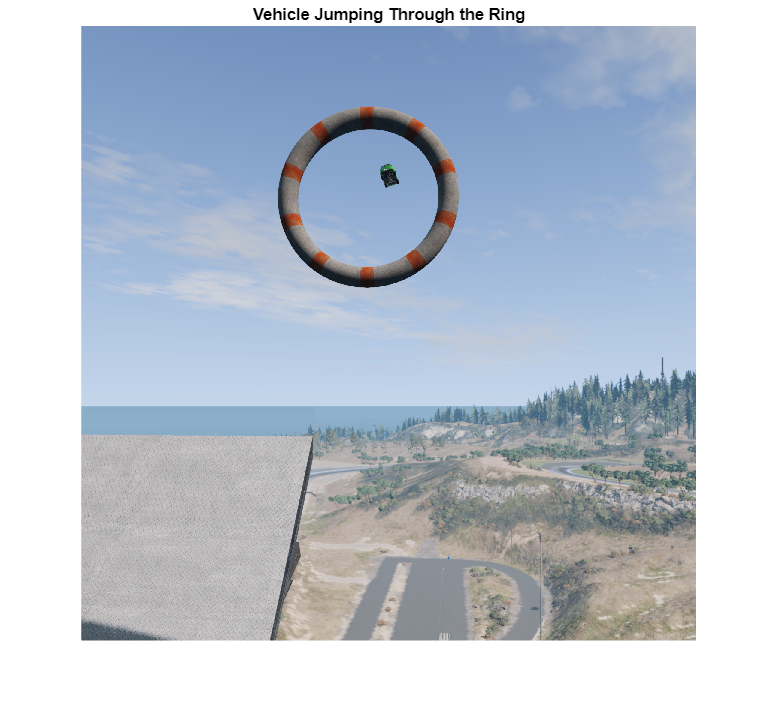

% Start the scenario
beamng.scenario.start();

% Query procedural meshes and find the ring position
meshes = scenario.find_procedural_meshes();
meshes = cell(meshes);
ring_pos = [];
for i = 1:length(meshes)
    if strcmp(char(meshes{i}.name), 'pyring')
        ring_pos = double(meshes{i}.pos);
        break;
    end
end

% Vehicle movement script
script = {
    py.dict(pyargs('x', -191.62, 'y', -160.32, 'z', 119.59, 't', 0)), ...
    py.dict(pyargs('x', -132.46, 'y', -116.09, 'z', 119.58, 't', 0.5)), ...
    py.dict(pyargs('x', -54.14, 'y', -59.21, 'z', 119.58, 't', 1)), ...
    py.dict(pyargs('x', 13.97, 'y', -9.83, 'z', 119.59, 't', 1.5)), ...
    py.dict(pyargs('x', 161.02, 'y', 96.44, 'z', 119.58, 't', 2)), ...
    py.dict(pyargs('x', 285.60, 'y', 189.41, 'z', 119.62, 't', 2.5)), ...
    py.dict(pyargs('x', 398.86, 'y', 267.55, 'z', 195.54, 't', 3))
};
vehicle.ai.set_script(script);

% Step the simulation forward
beamng.step(int32(600));

% Measure distance between vehicle and ring
scenario.update();
vehicle_pos = double(vehicle.state{'pos'});
distance = norm(vehicle_pos - ring_pos);
steps = 0;
while distance > 5 && steps < 300
    scenario.update();
    vehicle_pos = double(vehicle.state{'pos'});
    distance = norm(vehicle_pos - ring_pos);
    beamng.step(int32(5));
    steps = steps + 1;
end

if distance > 5
    error('The vehicle did not hit the ring!');
end


% Get camera images
frames = cam.poll();

beamng.close()
% Display the result
color_RGBA = double(py.numpy.array(frames{'colour'}));
color_RGB = color_RGBA(:, :, 1:3) / 256;
imshow(color_RGB);
xlim([0 cam_width])
ylim([0 cam_height])
title('Vehicle Jumping Through the Ring');
axis equal;